# Preparing Data


% Sequence Data (During Learning)
N_mems = 20; N_trials = 1000; N_lrnt = 300;
selected_trials =[];
for i = 1:N_mems
    selected_trials = [selected_trials, ((N_trials - N_lrnt ):999) + (i-1)*N_trials];
end
selected_trials = [selected_trials, [1000000+1 : 1000000 + N_mems*5]];
N_cells = size(check_flag_save2, 2);
sequenceData = check_flag_save2(selected_trials, :)'; % (N_cells , N_obsercvations)
sequenceData = mat2cell(sequenceData, N_cells, ones(1, size(sequenceData, 2))); 
sequenceLabels = categorical([repelem(1:N_mems, N_lrnt ), repelem(1:N_mems, 5)]);  % Discrete cluster labels
size(sequenceData), size(sequenceLabels)

ans =            1        6100


ans =            1        6100


## Splitting the Data to Train and Validation sets

% Define the train-validation split ratio
trainRatio = 0.80; % 80% for training, 20% for validation

% Number of samples
numSamples = length(sequenceData);

% Randomly shuffle indices
randIndices = randperm(numSamples);

% Determine the split point
splitIdx = round(trainRatio * numSamples);

% Split indices into training and validation sets
trainIndices = randIndices(1:splitIdx);
valIndices = randIndices(splitIdx+1:end);

% Split the sequence data into training and validation sets
trainData = sequenceData(trainIndices);
valData = sequenceData(valIndices);

% Split the labels into training and validation sets
trainLabels = sequenceLabels(trainIndices);
valLabels = sequenceLabels(valIndices);

## Network Architecture


inputSize = 400;   % Size of the input sequence
numHiddenUnits = 170;  % Number of LSTM units
numClasses = N_mems;  % Number of clusters/categories

layers = [
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits, 'OutputMode', 'last')  % 'last' takes the final output
  
    fullyConnectedLayer(numClasses)

    softmaxLayer
    classificationLayer];


## Options of Training

options = trainingOptions('adam', ...
    'MaxEpochs', 5, ...
    'MiniBatchSize', 170, ...
    'Shuffle', 'every-epoch', ...
    'Verbose', 0 ...
    );

## Training the neural net

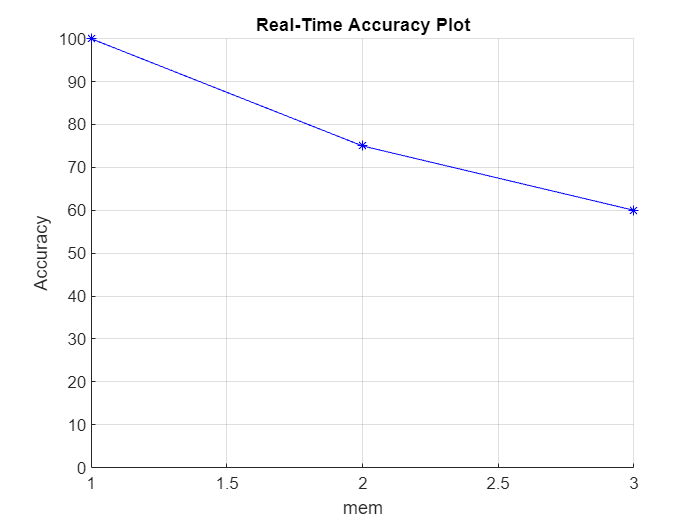

iter 3

accuracy 63
accuracy 94


iter 4

accuracy 89
accuracy 100


iter 5

accuracy 55
accuracy 68
accuracy 59
accuracy 51
accuracy 44
accuracy 39
accuracy 40
accuracy 44
accuracy 35
accuracy 33
accuracy 32
accuracy 44
accuracy 43
accuracy 32
accuracy 32
accuracy 33
accuracy 32
accuracy 33
accuracy 33
accuracy 32
accuracy 32
accuracy 32
accuracy 32
accuracy 32
accuracy 32
accuracy 32
accuracy 32
accuracy 32
accuracy 32
accuracy 32
accuracy 32
accuracy 32
accuracy 32
accuracy 32
accuracy 32
accuracy 31
accuracy 31
accuracy 32
accuracy 32
accuracy 33
accuracy 31
accuracy 32
accuracy 32
accuracy 32
accuracy 31
accuracy 32
accuracy 31
accuracy 33
accuracy 32
accuracy 32
accuracy 32
accuracy 31
accuracy 32
accuracy 32
accuracy 32
accuracy 32
accuracy 33
accuracy 33
accuracy 33
accuracy 32
accuracy 46
accuracy 38
accuracy 32
accuracy 33
accuracy 33
accuracy 38
accuracy 34
accuracy 33
accuracy 33
accuracy 48
accuracy 38
accuracy 33
accuracy 36
accuracy 54
accuracy 37
accuracy 43
accuracy 34
accuracy 34
accuracy 33
accuracy 40
accuracy 55
accuracy 43
accuracy 34
accu

iter 6

accuracy 50
accuracy 47
accuracy 48
accuracy 38
accuracy 32
accuracy 32
accuracy 32
accuracy 32
accuracy 32
accuracy 33
accuracy 33
accuracy 32
accuracy 32
accuracy 33
accuracy 31
accuracy 38
accuracy 36
accuracy 33
accuracy 43
accuracy 52
accuracy 62
accuracy 63
accuracy 41
accuracy 44
accuracy 38
accuracy 31
accuracy 34
accuracy 33
accuracy 33
accuracy 33
accuracy 32
accuracy 32
accuracy 32
accuracy 32
accuracy 35
accuracy 35
accuracy 32
accuracy 44
accuracy 43
accuracy 33
accuracy 32
accuracy 38
accuracy 48
accuracy 45
accuracy 45
accuracy 43
accuracy 36
accuracy 40
accuracy 32
accuracy 33
accuracy 34
accuracy 32
accuracy 33
accuracy 34
accuracy 33
accuracy 36
accuracy 34
accuracy 38
accuracy 40
accuracy 35
accuracy 42
accuracy 60
accuracy 38
accuracy 35
accuracy 39
accuracy 33
accuracy 33
accuracy 34
accuracy 43
accuracy 33
accuracy 36
accuracy 40
accuracy 32
accuracy 39
accuracy 37
accuracy 35
accuracy 33
accuracy 35
accuracy 34
accuracy 37
accuracy 34
accuracy 40
accuracy 36
accu

Max_mem = 100;
batchSize = 300;

% Initialize figure for real-time plotting
figure;
hold on;
grid on;
xlabel('mem');
ylabel('Accuracy');
title('Real-Time Accuracy Plot');
%xlim([0 Max_mem]);
ylim([0 100])

accuracyHistory = [];
for iter = 3:Max_mem
    fprintf("iter %d", iter)    
    acc = 0;
    while acc < 90
        [net, trainInfo] = trainNetwork(sequenceData((iter-3)*batchSize+1:iter*batchSize), sequenceLabels((iter-3)*batchSize+1:iter*batchSize), layers, options);
        acc = mean(trainInfo.TrainingAccuracy);
        fprintf("accuracy %1.f\n", acc) 
        layers = net.Layers;
        %options.MaxEpochs = 10 + 3*iter;
    end
    %options.MiniBatchSize = options.MiniBatchSize + 10;

    % Store accuracy for this epoch
    predictedLabels = classify(net, sequenceData(1:iter*batchSize));
    acc = 100* sum(sequenceLabels(1:iter*batchSize)' == predictedLabels)/numel(predictedLabels);
    accuracyHistory = [accuracyHistory, acc];

    % Plot accuracy in real-time
    plot(accuracyHistory, 'b*-');
    drawnow; % Update the plot in real-time
    %length(trainInfo.TrainingAccuracy)
end

## Hyper Paramter Optimization (Bayesian Optimization)

% Define the variables to optimize
optimVars = [
    optimizableVariable('numHiddenUnits', [50, 200], 'Type', 'integer')
    optimizableVariable('miniBatchSize', [20, 200], 'Type', 'integer')
    optimizableVariable('InitialLearnRate', [1e-3, 1e-2], 'Transform', 'log')];

% Define the objective function to minimize
ObjFcn = @(x)trainLSTMModel(x.numHiddenUnits, x.miniBatchSize, x.InitialLearnRate, ...
    trainData, trainLabels, valData, valLabels);

% Run Bayesian optimization
results = bayesopt(ObjFcn, optimVars, ...
    'MaxObjectiveEvaluations', 10, ...
    'IsObjectiveDeterministic', false, ...
    'UseParallel', true ...
    ); 

bestHyperparameters = results.XAtMinObjective;
disp(bestHyperparameters);


% inputSize = 400;   % Size of the input sequence
% numHiddenUnits = 50;  % Number of LSTM units
% numClasses = N_mems;  % Number of clusters/categories
% 
% layers = [
%     sequenceInputLayer(inputSize)
%     lstmLayer(numHiddenUnits, 'OutputMode', 'last')  % 'last' takes the final output
% 
%     fullyConnectedLayer(numClasses)
% 
%     softmaxLayer
%     classificationLayer];
% 
% options = trainingOptions('adam', ...
%     'MaxEpochs', 20, ...
%     'MiniBatchSize', 200, ...
%     'Shuffle', 'every-epoch', ...
%     'Verbose', 0 , ...
%     'Plots','training-progress' ...
% );
% 
% [net, trainInfo] = trainNetwork(trainData, trainLabels, layers, options);

## Validation on validation set

% Use the trained network to classify the test sequences
predictedLabels = classify(net, trainData)
% Compute the accuracy
accuracy = sum(predictedLabels == trainLabels') / numel(trainLabels);
fprintf('Test Accuracy: %.2f%%\n', accuracy * 100);

## Function for generating cummualtive training set

function [trainDataBatch, trainLabelsBatch] = dataGenerator(sequenceData, sequenceLabels, epoch, maxEpochs)
    % Total number of samples
    numSamples = length(sequenceData);
    
    % Dynamically change the batch size (subset size)
    % For example, you can gradually increase the subset size with each epoch
    minSubsetSize = 100; % Minimum subset size
    maxSubsetSize = round(0.5 * numSamples); % Maximum subset size, 50% of data
    
    % Calculate current subset size (you can adjust this rule as needed)
    subsetSize = minSubsetSize + round((epoch / maxEpochs) * (maxSubsetSize - minSubsetSize));

    % Select a random subset of indices with the calculated subset size
    subsetIndices = randperm(numSamples, subsetSize);
    
    % Generate the training subset
    trainDataBatch = sequenceData(subsetIndices);
    trainLabelsBatch = sequenceLabels(subsetIndices);
end

function valError = trainLSTMModel(numHiddenUnits, miniBatchSize, InitialLearnRate, trainData, trainLabels, valData, valLabels)
    layers = [
        sequenceInputLayer(400)
        lstmLayer(numHiddenUnits, 'OutputMode', 'last')
        fullyConnectedLayer(max(double(trainLabels))) % Assuming 10 classes
        softmaxLayer
        classificationLayer];

    options = trainingOptions('adam', ...
        'MaxEpochs', 5, ...
        'MiniBatchSize', miniBatchSize, ...
        'InitialLearnRate', InitialLearnRate, ...
        'ValidationData', {valData, valLabels}, ...
        'Verbose', 0);
    
    % Train the network and obtain validation accuracy
    [~, trainInfo] = trainNetwork(trainData, trainLabels, layers, options);
    valError = -max(trainInfo.ValidationAccuracy); % Maximize accuracy
end